clear 
close all
clc
% To load the data
%addpath('C:\Users\20182270\OneDrive - TU Eindhoven\Documents\0 Graduation project\Matlab')
%savepath
%dr = loadvec('C:\Users\20182270\OneDrive - TU Eindhoven\Documents\0 Graduation project\Matlab\Input\20240408\Results\Basler_acA2040-90uc__21599070__20240408_111238612_0001_diff_new.dat')
dr = loadvec('D:\Matlab input\20240715_full_plate\20240715_nonrot_2.6Hz_9mm_full_plate_separate_frames\Results\20240715_nonrot_2.6Hz_9mm_full_plate_frame_0150A_vel_new.dat');


% Copy dr to dr_new & delete rows and columns with only zeros

dr_new=dr;
%vx=dr.vx;
% Delete zeros for x comp
% dr_new.x(:,all(dr_new.vx == 0,1))=[];
dr_new.x(:,all(dr_new.vy == 0,2))=[];
% 
dr_new.y(:,all(dr_new.vy == 0,1))=[];
% dr_new.y(all(dr_new.vy == 0,2),:)=[];

dr_new.vx(:,all(dr_new.vx == 0,1))=[];
dr_new.vx(all(dr_new.vx == 0,2),:)=[];

dr_new.vy(:,all(dr_new.vy == 0,1))=[];
dr_new.vy(all(dr_new.vy == 0,2),:)=[];




% Compute the surface height

%h_0 = 13/0.15; % 1 pixel is 0.15 mm % 11 mm % surface-pattern distance in mm
h_0 = 150; % 150 surface-pattern distance in mm
h = surfheight(dr_new,h_0);

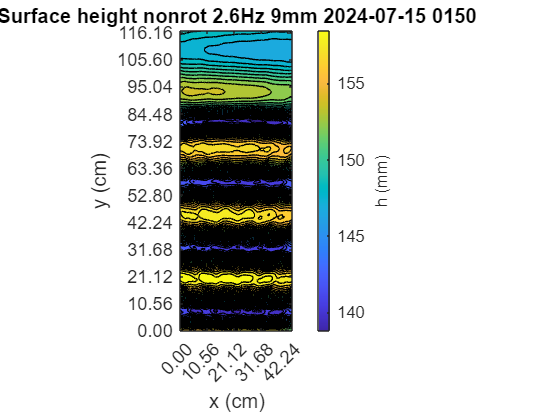

% Plot the surface height & save figure

%surf(h.w)
%showf(h.w)
contourf(h.w, 25);
axis equal
ax = gca;
numbers_long_axis = (dr_new.x-47.52)./10;
numbers_short_axis = (dr_new.y+594.001)./10;

% Determine the positions of the ticks you want to display (e.g., every 10th label)
x_tick_positions = 1:40:length(numbers_short_axis);
y_tick_positions = 1:40:length(numbers_long_axis);

% Set the ticks at these positions
ax.XTick = x_tick_positions;
ax.YTick = y_tick_positions;

% % Manually format the labels to have a consistent exponent
% x_tick_labels = numbers_short_axis(x_tick_positions) / 1e1;
% y_tick_labels = numbers_long_axis(y_tick_positions) / 1e1;

% ax.XTickLabel = arrayfun(@(x) sprintf('%.2f\\times10^1', x), x_tick_labels, 'UniformOutput', false);
% ax.YTickLabel = arrayfun(@(y) sprintf('%.2f\\times10^1', y), y_tick_labels, 'UniformOutput', false);
% 

% % Set the labels at these positions
% ax.XTickLabel = numbers_short_axis(x_tick_positions);
% ax.YTickLabel = numbers_long_axis(y_tick_positions);
% 
% % Set the tick format to scientific notation
% xtickformat('%0.1e');
% ytickformat('%0.1e');

% Set the labels at these positions and format them to 2 decimal places
ax.XTickLabel = arrayfun(@(x) sprintf('%.2f', x), numbers_short_axis(x_tick_positions), 'UniformOutput', false);
ax.YTickLabel = arrayfun(@(y) sprintf('%.2f', y), numbers_long_axis(y_tick_positions), 'UniformOutput', false);

title('Surface height nonrot 2.6Hz 9mm 2024-07-15 0150')
col = colorbar;
xlabel('x (cm)');
ylabel('y (cm)');
ylabel(col,'h (mm)');

%caxis([140, 160]);
%w=h.w
%exportgraphics(gcf,'C:\Users\20182270\OneDrive - TU Eindhoven\Documents\0 Graduation project\Matlab\Output\20240618_new_A3_results\20240618_rot_2Hz_5mm_new_A3_frame_surface_height_0145.png')